# Results of AR modeling

This live script visualizes the results of the experiments

## First experiment sets

names = {'AR(10)', 'svd', 'cpd_s', 'cpd_f', 'cpd_{cols}', 'cpd_{colf}', 'mlsvd'};

### Dimensions of L

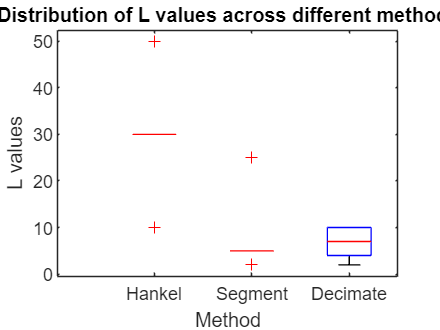

% Create a new figure
figure;
hold on;

% Prepare the data for boxplot
data = [best_dimensions_hankel(:, 1), best_dimensions_segment(:, 1), best_dimensions_decimate(:, 1)];
group = [ones(size(best_dimensions_hankel, 1), 1); 
         2 * ones(size(best_dimensions_segment, 1), 1); 
         3 * ones(size(best_dimensions_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('L values');
title('Distribution of L values across different methods');

### dimensions of L Dot plot 

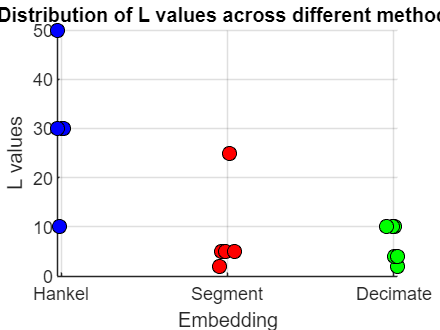


% Create a new figure
figure;
hold on;

% Prepare the data
data_hankel = best_dimensions_hankel(:, 1);
data_segment = best_dimensions_segment(:, 1);
data_decimate = best_dimensions_decimate(:, 1);

% Define x positions for each group with jitter
jitterAmount = 0.1;  % Adjust the jitter amount as needed
x_hankel = 1 + (rand(size(data_hankel)) - 0.5) * jitterAmount;
x_segment = 2 + (rand(size(data_segment)) - 0.5) * jitterAmount;
x_decimate = 3 + (rand(size(data_decimate)) - 0.5) * jitterAmount;

% Plot the data points
scatter(x_hankel, data_hankel, 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'b');
scatter(x_segment, data_segment, 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'r');
scatter(x_decimate, data_decimate, 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'g');

% Label the plot
xlabel('Embedding');
ylabel('L values');
title('Distribution of L values across different methods');
set(gca, 'XTick', [1 2 3], 'XTickLabel', {'Hankel', 'Segment', 'Decimate'});

% Optional: Add grid for better readability
grid on;
hold off;

### Dimensions of M

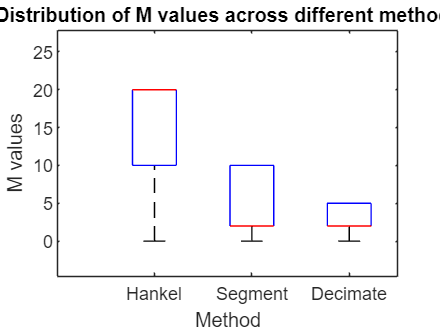

% Create a new figure
figure;
hold on;


% Prepare the data for boxplot
data = [best_dimensions_hankel(:, 2), best_dimensions_segment(:, 2), best_dimensions_decimate(:, 2)];
group = [ones(size(best_dimensions_hankel, 1), 1); 
         2 * ones(size(best_dimensions_segment, 1), 1); 
         3 * ones(size(best_dimensions_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('M values');
title('Distribution of M values across different methods');

### dimensions of M Dot plot 

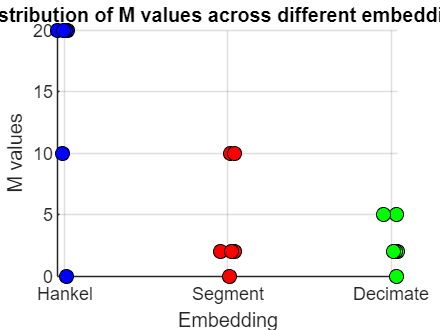

% Create a new figure
figure;
hold on;

% Prepare the data
data_hankel = best_dimensions_hankel(:, 2);
data_segment = best_dimensions_segment(:, 2);
data_decimate = best_dimensions_decimate(:, 2);

% Define x positions for each group with jitter
jitterAmount = 0.1;  % Adjust the jitter amount as needed
x_hankel = 1 + (rand(size(data_hankel)) - 0.5) * jitterAmount;
x_segment = 2 + (rand(size(data_segment)) - 0.5) * jitterAmount;
x_decimate = 3 + (rand(size(data_decimate)) - 0.5) * jitterAmount;

% Plot the data points
scatter(x_hankel, data_hankel, 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'b');
scatter(x_segment, data_segment, 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'r');
scatter(x_decimate, data_decimate, 50, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'g');

% Label the plot
xlabel('Embedding');
ylabel('M values');
title('Distribution of M values across different embeddings');
set(gca, 'XTick', [1 2 3], 'XTickLabel', {'Hankel', 'Segment', 'Decimate'});

% Optional: Add grid for better readability
grid on;
hold off;

### Distribution of R values

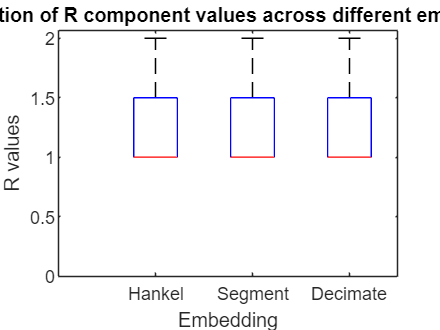

% Create a new figure
figure;
hold on;

new_fields = size(best_dimensions_hankel,1);

% Define a set of colors or markers for different fields
colors = lines(new_fields); % Using lines colormap for distinct colors
jitterAmount = 0.3;

% Prepare the data for boxplot
data = [best_comp_hankel(:, 1), best_comp_segment(:, 1), best_comp_decimate(:, 1)];
group = [ones(size(best_comp_hankel, 1), 1); 
         2 * ones(size(best_comp_segment, 1), 1); 
         3 * ones(size(best_comp_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Embedding');
ylabel('R values');
title('Distribution of R component values across different embeddings');

### Distribution of threshold values

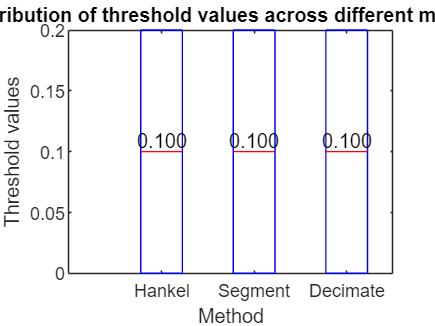

% Create a new figure
figure;
hold on;

% Prepare the data for boxplot
data = [best_thresh_hankel(:, 1); best_thresh_segment(:, 1); best_thresh_decimate(:, 1)];
group = [ones(size(best_thresh_hankel, 1), 1); 
         2 * ones(size(best_thresh_segment, 1), 1); 
         3 * ones(size(best_thresh_decimate, 1), 1)];

% Create the boxplot
boxplot(data, group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Calculate medians
medians = grpstats(data, group, 'median');

% Label the plot
xlabel('Method');
ylabel('Threshold values');
title('Distribution of threshold values across different methods');

% Add numbers next to the medians
positions = [1, 2, 3];
for i = 1:length(medians)
    text(positions(i), medians(i), sprintf('%.3f', medians(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

% Adjust Y-axis limits to fully use the vertical axis
ylim auto; % Automatically set the limits based on the data

hold off;

### Normalized RMSE across different signal parameters

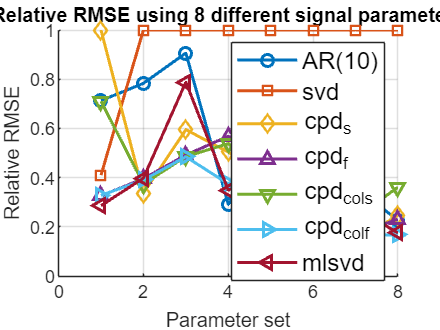

% Prepare the data
rmseValues = zeros(8,7);
for i = 1:7
    rmseValues(:,i) = squeeze(ex9gt1mean(3,i+1,:));
end
rmseValuesNorm = rmseValues ./ max(rmseValues, [], 2);

% Create a new figure
figure;
hold on;

% Define colors and markers
colors = lines(7); % Use MATLAB's lines colormap
markers = {'o', 's', 'd', '^', 'v', '>', '<'};

% Plot each normalized RMSE
for i = 1:7
    plot(rmseValuesNorm(:,i), 'Color', colors(i,:), 'Marker', markers{i}, 'LineWidth', 1.5, 'DisplayName', names{i});
end

% Add grid, labels, and title
grid on;
legendHandle = legend(names, 'location', 'northeast');
set(legendHandle, 'FontSize', 12); % Increase legend font size

xlabel('Parameter set');
ylabel('Relative RMSE');
title('Relative RMSE using 8 different signal parameters');

% Release the hold on the figure
hold off;

### Normalized RMSE mean over signal parameters for all embeddings 

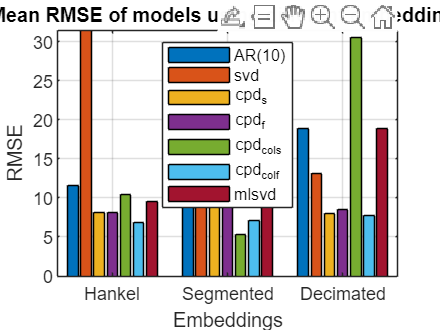

% Prepare the data
perfHankel = zeros(8,7);
perfSegment = zeros(8,7);
perfDecimate = zeros(8,7);

measure =3;

%the respective measurements compared to the column numbers 1=mean, 2=sd,
%etc.
measureNames = ["mean", "SD", "RMSE", "Relative Error", "L2 Relative Error","Runtime"];

for i = 1:7
    perfHankel(:,i) = squeeze(ex9gt1mean(measure,i+1,:));
    perfSegment(:,i) = squeeze(ex11gt1mean(measure,i+1,:));
    perfDecimate(:,i) = squeeze(ex13gt1mean(measure,i+1,:));
end

% Example data (replace with your actual data)
perfHankelMed = mean(perfHankel, 1);
perfSegmentMed = mean(perfSegment, 1);
perfDecimateMed = mean(perfDecimate, 1);

% Combine the data into one matrix
sortedData = [perfHankelMed; perfSegmentMed; perfDecimateMed];

% Model names
modelNames = {'AR(10)', 'svd', 'cpd_s', 'cpd_f', 'cpd_{cols}', 'cpd_{colf}', 'mlsvd'};

% Create a new figure
figure;

% Plot the data as grouped bars
bar(sortedData);

% Set the legend and labels
legend(modelNames, 'Orientation', 'vertical', 'Location', 'north');
xticks([1 2 3]);
xticklabels({'Hankel', 'Segmented', 'Decimated'});
xlabel('Embeddings');
ylabel([measureNames(measure)]);
title("Mean "+ measureNames(measure)+" of models using different embeddings");
grid on;

% means of the different embeddings

ex9all = mean(ex9gt1mean,3)

ex9all =    4.801174615508766   5.321170689301662  10.952428529972824   0.918070224463564   1.119455525466095  -0.581195802487844  -0.473698082740770   3.243756459262491
                   0   0.000000000000002   0.000000000000004   0.000000000000001   0.000000000000001   1.188189091708823   0.000000000000001   0.000000000000001
                   0  11.631181760772474  31.487494149225537   8.093788354617203   8.097132466756063  10.416881353697267   6.848906349569778   9.505009692920730
                   0   4.287364017495319  14.864717636929786   4.260335102612995   2.894399316858827   5.239929976724392   1.935853585607432   4.465763723232037
                   0   4.799313955813522  15.372229985400878   4.467929349154447   3.219941785208178   5.695716919000592   2.119227462974595   4.981642816462085
                   0   0.077524725250000   3.704159021750000   0.157005963000000   0.165410499625000   0.522540413125000   0.188520902500000   0.082633704750000


ex11all = mean(ex11gt1mean,3)

ex11all =    4.612091474868321   1.077324292413611  -1.658187446782029   1.556647949843187  -2.298309454002440   5.247181269940939   4.581090590155633   0.014111496114035
                   0   0.000000000000002   0.000000000000002   0.000000000000002   0.000254081014698   0.000000000000001   0.000000000000001   0.000000000000001
                   0  15.306152883559450  13.822404425710642  14.452797984388120  10.352659911747349   5.309706011705298   7.148531181579976  13.978448009988497
                   0   3.979361305286192   3.872737314510266   5.159525592973369   3.792335697441320   1.406288961603792   1.858067840279548   3.313401371510044
                   0   4.281191032121276   4.236205106596388   5.500433574823683   4.107028798083089   1.921483108559164   2.153174551156787   3.485243264685254
                   0   0.073130423375000   0.297813175000000   0.100222977250000   0.137946724250000   0.082982612250000   0.089285419125000   0.076024347125000


ex13all = mean(ex13gt1mean,3)

ex13all =    4.260458829923665   2.548998773875066  -0.361493578499573  -1.521559466221447  -3.198901549727431  -1.002159396994272   3.565339437478948   2.548991760752772
                   0   0.000000000000002   0.000000000000002   0.000000000000001   0.000000000000001   0.000200619079990   0.000000000000001   0.000000000000003
                   0  18.908258856323719  13.165105487462759   8.040684902724481   8.548887518120225  30.544986637520083   7.768715690591464  18.908251843201437
                   0  22.497899537023105  15.895851781114459   8.510256996172721  15.036357170561757   8.933950726006659   5.642536149268015  22.497898457733250
                   0  22.859933937095050  16.164362554492737   8.772383942071608  15.282783084891607   9.272283539958080   5.879327248471036  22.859932857805191
                   0   0.071873341500000   0.240259947875000   0.095635605875000   0.095762137250000   0.162890794125000   0.086354662375000   0.080541623250000


### Normalized mean RMSE over all signal parameters 10 points ahead

% Calculate the mean and normalize the data
ex18all = mean(ex18gt1mean, 3)

ex18all =   14.139344360099056  13.402758205534374  14.260849206904421  11.744167306414845   9.653095974295145   6.344030885372740  14.587840110332492
  18.171235144147339  16.038744707729819  23.843646266266795  15.398663133982872  16.374997795111852  13.401476821999561  18.669552823105946
  20.290685081777522  22.811036132788594  30.064475507928400  19.869828519716776  17.851839965490214  20.854648914391298  21.342663816222750
  16.095380511893133  25.385923131876986  28.012601663712900  21.901444674923695  19.334988974173868  24.059073314634126  16.991592550006985
  22.867500626498281  22.093291294801347  26.592818367031107  22.719415116417519  21.184550067975490  24.735058372923767  23.302522357715709
  17.435727033625575  18.206690156298151  19.314186764870730  17.511690325769123  14.677402015333630  15.686770559066796  16.137025049521100
  18.437634529813739  16.612085302742049  15.983889167068426  16.781889854921634  12.795238574669224  13.964936096252615  16.706673389960486
  1


format long;
ex18allmean = mean(ex18all,1)

ex18allmean =   16.682863755852487  17.976087026395355  20.183418558394777  16.758302078191189  14.927762505533341  15.457196571592430  16.896449586852423


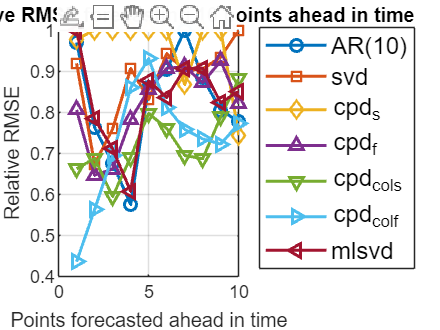


ex18allNorm = ex18all ./ max(ex18all, [], 2);

% Define model names
names = {'AR(10)', 'svd', 'cpd_s', 'cpd_f', 'cpd_{cols}', 'cpd_{colf}', 'mlsvd'};

% Create a new figure
figure;
hold on;

% Define colors and markers for better distinction
colors = lines(7); % Use MATLAB's lines colormap for distinct colors
markers = {'o', 's', 'd', '^', 'v', '>', '<'};

% Plot each normalized RMSE line with distinct colors and markers
for i = 1:7
    plot(ex18allNorm(:,i), 'Color', colors(i,:), 'Marker', markers{i}, 'LineWidth', 1.5, 'DisplayName', names{i});
end

% Customize the plot
xlabel('Points forecasted ahead in time');
ylabel('Relative RMSE');
title('Mean Relative RMSE forecasting 10 points ahead in time');
grid on;

legendHandle = legend(names, 'location', 'northeastoutside');
set(legendHandle, 'FontSize', 12); % Increase legend font size

% Enhance readability with grid lines
grid on;
box on;

% Release the hold on the figure
hold off;

### Normalized mean RMSE over all signal parameters 10 points ahead zoomed in

logical = [true false false false true true false];
ex18allNorm2 = ex18all(:, logical) ./ max( ex18all(:, logical), [], 2)

ex18allNorm2 =    1.000000000000000   0.682711710561063   0.448679282702490
   1.000000000000000   0.901149408128482   0.737510505790574
   0.972957404608974   0.856012490968912   1.000000000000000
   0.668994200292120   0.803646454762379   1.000000000000000
   0.924497540362799   0.856458462663875   1.000000000000000
   1.000000000000000   0.841800401384330   0.899691221869565
   1.000000000000000   0.693973977734468   0.757414736346533
   1.000000000000000   0.776343320565994   0.831062547007471
   1.000000000000000   0.979915519306909   0.897187348652672
   0.881997076348056   1.000000000000000   0.876510229121605


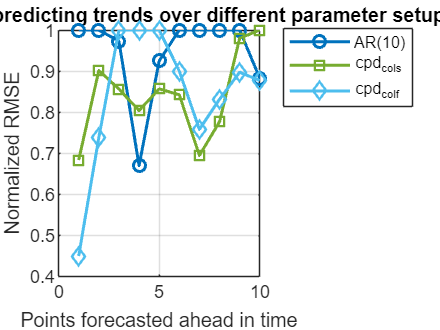


% Create a new figure
figure;
hold on;

betterModelNames = names(logical);
betterModedColors = colors(logical,:);
betterMarkers = markers(logical);

% Plot each normalized RMSE line with distinct colors and markers
for i = 1:length(betterModelNames)
    plot(ex18allNorm2(:,i), 'Color', betterModedColors(i,:), 'Marker', markers{i}, 'LineWidth', 1.5, 'DisplayName', betterModelNames{i});
end

% Customize the plot
legend('Location', 'northeastoutside', 'Orientation', 'vertical');
xlabel('Points forecasted ahead in time');
ylabel('Normalized RMSE');
title('RMSE values predicting trends over different parameter setups');
grid on;

% Enhance readability with grid lines
grid on;
box on;

% Release the hold on the figure
hold off;